## Field-weakening for Surface-Mounted Permanent Magnets Synchronous Motors (SMPMSM)

Hiba Houmsi, Federico Bribiesca Argomedo, Paolo Massioni, Romain Delpoux

Univ Lyon, INSA Lyon, Université Claude Bernard Lyon 1, Ecole Centrale de Lyon, CNRS, Ampère, UMR5005 Villeurbanne, France

### Model of the SPMSM

Using Clarke and Park transformations, the Smodel mathamtical model in the d-q frame is expressed as:


$$\begin{array}{l}
L\frac{{\textrm{di}}_{\textrm{dq}} }{\textrm{dt}}=v_{\textrm{dq}} -{\textrm{Ri}}_{\textrm{dq}} -p\omega {\textrm{LJi}}_{\textrm{dq}} -e_{\textrm{dq}} \\
\tau =\frac{3}{2}p\phi_f i_q 
\end{array}$$


with the roation matrix $J$given by:


$$J=\left\lbrack \begin{array}{cc}
0 & -1\\
1 & 0
\end{array}\right\rbrack$$


and the Back Electromotive Force (BEMF):


$$e_{\textrm{dq}} =p\phi_f \omega \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


The Smodel is mainly subject to two constraints:


$$||i_{\textrm{dq}} ||^2 =i_d^2 +i_q^2 \le I_{\max }^2$$



$$||v_{\textrm{dq}} ||^2 =v_d^2 +v_q^2 \le V_{\max }^2$$


### Formulation of the optimization problem

The desired bhavior is the minimum steady state currents $i_{\textrm{dq}}$to reach a given speed $\omega$ at a specific torque $\tau$ under the current and voltage constraints. The mathematical formulation is given by: 


$$\begin{array}{l}
\min_{i_{d,} i_q \;} \;i_d^2 +i_q^2 \\
\mathrm{s}\ldotp \mathrm{t}\ldotp \\
v_{\textrm{dq}} -{\textrm{Ri}}_{\textrm{dq}} -p\omega {\textrm{LJi}}_{\textrm{dq}} -e_{\textrm{dq}} =0\\
||i_{\textrm{dq}} ||^2 =i_d^2 +i_q^2 \le I_{\max }^2 \\
||v_{\textrm{dq}} ||^2 =v_d^2 +v_q^2 \le V_{\max }^2 \\
i_{q\;} =\frac{2}{3}\frac{\tau }{p\phi_f }
\end{array}$$


### Motor Parameters

 
model.R = 0.656;         % Ohm
model.L = 0.35e-3;       % H
model.Phif = 6.6e-3;     % Wb
model.p = 4;
model.omMax = 700;       % rad/s
model.vMax = 12;         % V
model.iMax = 10;         % A
model.iMin = 1 ;       % A
model.tauMax = 3/2*model.p*model.Phif*model.iMax;
model.omBase = calc_w_base(model);
disp(model);

         R: 0.6560
         L: 3.5000e-04
      Phif: 0.0066
         p: 4
     omMax: 700
      vMax: 12
      iMax: 10
      iMin: 1
    tauMax: 0.3960
    omBase: 194.2360



## Flield weakening

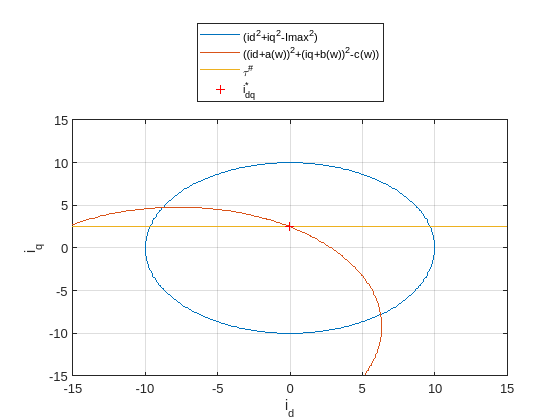

 
omMax = model.omMax;
tauMax = model.tauMax;
imax = model.iMax;
imin = model.iMin ; 
Imax =10;
w = 390;
tauEm = 0.1;


K = @(w) model.p*w*model.Phif/(model.R^2+(model.p*w*model.L)^2);
a = @(w) K(w)*model.p*w*model.L ;
b =  @(w) K(w)*model.R;
c = @(w) model.vMax^2/(model.R^2+(model.p*w*model.L)^2);

kappa1 = @(w) (-a(w).^2-b(w).^2+c(w)-Imax^2)./(2*a(w));
kappa2 = @(w) -b(w)/a(w);
delta = @(w) 4*(Imax^2*(kappa2(w).^2+1)-kappa1(w).^2);

i1 = @(w) (sqrt(c(w)-a(w)^2)-b(w));
i2 = @(w) ((-2*kappa1(w).*kappa2(w)+sqrt(delta(w)))./(2*(kappa2(w).^2+1)));
i4 = @(w) (sqrt(c(w))-b(w));
iref  = 2*tauEm/(3*model.p*model.Phif);

if (i1(w)>=iref | i1(w)>=Imax)
    idref = 0;
    iqref = min(iref,Imax);
else
    if(i1(w)<i2(w) &  ~((i2(w))^2+(-sqrt(c(w)-(i2(w)+b(w))^2)-a(w))^2 <= Imax^2 + 1e-12) & delta(w)>0)
        isat = min(i2(w),Imax);
    else
        isat = min(i4(w),Imax);
    end 
    
    if iref > min(isat,Imax)
       iref = min(isat,Imax);
    end
       idref = sqrt(c(w)-(iref+b(w))^2)-a(w);
       iqref = iref;

    if iqref <0 % Defined for positive toeque here.
        iqref = NaN ;
        idref = NaN
    end
    if (delta(w) < 0 & ~((i2(w))^2+(-sqrt(c(w)-(i2(w)+b(w))^2)-a(w))^2 <=  Imax^2+1e-12))
     disp("no solution ")
    idref = NaN 
    iqref = NaN
    end 
end

n= 1.5;  
Fi = @(id,iq) ( id.^2 + iq.^2 - Imax.^2); %% Current limit 
Fv = @(id,iq) ( (id+a(w)).^2 + (iq+b(w)).^2 - c(w)); %% Voltage limit
hi = fimplicit(Fi,n*[-Imax Imax -Imax Imax]); hold on;
hv = fimplicit(Fv,n*[-Imax Imax -Imax Imax]);
hiq=plot(n*[-Imax Imax],[iqref iqref],'DisplayName','\tau^#');
href = plot(idref,iqref,'r+','DisplayName','i_{dq}^*'); hold off;
l=legend; l.Location = 'northoutside';
axis(n*[-Imax Imax -Imax Imax]);
grid on
xlabel('i_d')
ylabel('i_q')

### References : 

H. Houmsi et al. "A Karush-Kuhn-Tucker approach to field-weakening for Surface-Mounted Permanent Magnets Synchronous Motors" ICCAD 2023, Rome

Function

function omBase = calc_w_base(pmsm)
    K = @(w) pmsm.p*w*pmsm.Phif./(pmsm.R.^2+(pmsm.p*w*pmsm.L).^2);
    a = @(w) K(w).*pmsm.p.*w.*pmsm.L;
    b = @(w) K(w).*pmsm.R;
    c = @(w) pmsm.vMax^2./(pmsm.R^2+(pmsm.p*w.*pmsm.L).^2);

    syms w_base ;
    assume(w_base','real');
    assume(w_base','positive');
    eqn = (sqrt(c(w_base)-a(w_base)^2)-b(w_base))==pmsm.iMax;
    omBase = double(vpa(solve(eqn,w_base)));
end
